addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 3, part a) NATURAL CUBIC SPLINE

xData = [-8 2 5 9];
yData = [99 90 50 -31];

natSplines = naturalCubicSpline(xData, yData)

$$natSplines = \left(\begin{array}{c} \frac{3641\,x}{1065}-\frac{9199\,{\left(x+8\right)}^{3}}{213000}+\frac{134563}{1065}\\ \frac{647\,{\left(x-2\right)}^{3}}{63900}-\frac{9199\,{\left(x-2\right)}^{2}}{7100}-\frac{4063\,x}{426}+\frac{23233}{213}\\ \frac{1069\,{\left(x-5\right)}^{3}}{10650}-\frac{2138\,{\left(x-5\right)}^{2}}{1775}-\frac{362909\,x}{21300}+\frac{575909}{4260} \end{array}\right)$$

vpa(expand(natSplines),4) % view in decimal form

$$ans = \left(\begin{array}{c} -0.04319\,x^{3}-1.037\,x^{2}-4.873\,x+104.2\\ 0.01013\,x^{3}-1.356\,x^{2}-4.234\,x+103.8\\ 0.1004\,x^{3}-2.71\,x^{2}+2.535\,x+92.53 \end{array}\right)$$

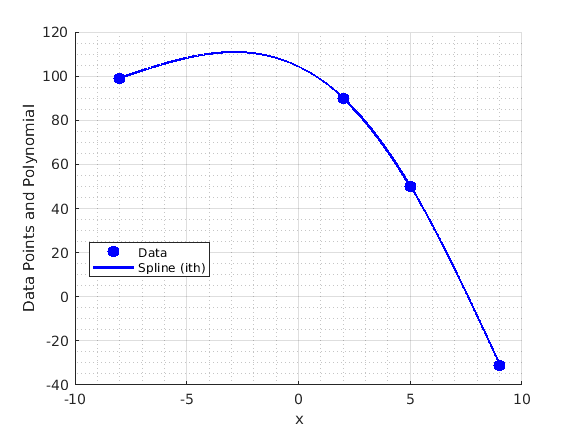

% plotting
plotSplines(xData, yData, natSplines)

Solving the system with rref function (not by hand work)

% a1 b1 c1 d1 a2 b2 c2 d2 a3 b3 c3 d3
N = sym([0 1 0 0 0 0 0 0 0 0 0 0; 
    1000 100 10 1 0 0 0 0 0 0 0 0;
    0 0 0 0 27 9 3 1 0 0 0 0;
    0 0 0 0 0 0 0 0 64 16 4 1;
    300 20 1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 27 6 1 0 0 0 -1 0;
    0 0 0 0 0 0 0 0 24 2 0 0;
    60 2 0 0 0 -2 0 0 0 0 0 0;
    0 0 0 0 18 2 0 0 0 -2 0 0;
    0 0 0 1 0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 1])

$$N = \left(\begin{array}{cccccccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1000 & 100 & 10 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 9 & 3 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 64 & 16 & 4 & 1\\ 300 & 20 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 6 & 1 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 24 & 2 & 0 & 0\\ 60 & 2 & 0 & 0 & 0 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 18 & 2 & 0 & 0 & 0 & -2 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

n = sym(transpose([0 90 50 -31 0 0 0 0 0 99 90 50]))

$$n = \left(\begin{array}{c} 0\\ 90\\ 50\\ -31\\ 0\\ 0\\ 0\\ 0\\ 0\\ 99\\ 90\\ 50 \end{array}\right)$$

coefsNat = linsolve(N, n);
ones = coefsNat(1:4);
twos = coefsNat(5:8);
threes = coefsNat(9:12);
a1 = ones(1); b1 = ones(2); c1 = ones(3); d1 = ones(4);
a2 = twos(1); b2 = twos(2); c2 = twos(3); d2 = twos(4);
a3 = threes(1); b3 = threes(2); c3 = threes(3); d3 = threes(4);

[a1, b1, c1, d1] 

$$ans = \left(\begin{array}{cccc} -\frac{9199}{213000} & 0 & \frac{3641}{1065} & 99 \end{array}\right)$$


[a2 b2 c2 d2]

$$ans = \left(\begin{array}{cccc} \frac{647}{63900} & -\frac{9199}{7100} & -\frac{4063}{426} & 90 \end{array}\right)$$


[a3 b3 c3 d3]

$$ans = \left(\begin{array}{cccc} \frac{1069}{10650} & -\frac{2138}{1775} & -\frac{362909}{21300} & 50 \end{array}\right)$$

% or using the rref function
Nd = double(N)

Nd =            0           1           0           0           0           0           0           0           0           0           0           0
        1000         100          10           1           0           0           0           0           0           0           0           0
           0           0           0           0          27           9           3           1           0           0           0           0
           0           0           0           0           0           0           0           0          64          16           4           1
         300          20           1           0           0           0          -1           0           0           0           0           0
           0           0           0           0          27           6           1           0           0           0          -1           0
           0           0           0           0           0           0           0           0          24           2     

nd = double(n)

nd =      0
    90
    50
   -31
     0
     0
     0
     0
     0
    99
    90
    50


coefsNatDouble = rref([Nd, nd])

coefsNatDouble =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0  -0.043165467625899
                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0   3.418604651162791
                   0                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   0

coefsNatDouble = coefsNatDouble(:, end)

coefsNatDouble =   -0.043165467625899
                   0
   3.418604651162791
  99.000000000000000
   0.010101010101010
  -1.295454545454545
  -9.537500000000000
  90.000000000000000
   0.100371747211896
  -1.204545454545455
 -17.037974683544302
  50.000000000000000


% See that they are (almost) equal
[double(vpa(coefsNat)), coefsNatDouble]

ans =   -0.043187793427230  -0.043165467625899
                   0                   0
   3.418779342723005   3.418604651162791
  99.000000000000000  99.000000000000000
   0.010125195618153   0.010101010101010
  -1.295633802816901  -1.295454545454545
  -9.537558685446010  -9.537500000000000
  90.000000000000000  90.000000000000000
   0.100375586854460   0.100371747211896
  -1.204507042253521  -1.204545454545455
 -17.037981220657276 -17.037974683544302
  50.000000000000000  50.000000000000000


Part b) clamped cubic splines

clmpSplines = clampedCubicSpline(xData, yData, 1, -1)

$$clmpSplines = \left(\begin{array}{c} x+\frac{8401\,{\left(x+8\right)}^{2}}{32400}-\frac{14557\,{\left(x+8\right)}^{3}}{324000}+107\\ \frac{169429}{1620}-\frac{3527\,{\left(x-2\right)}^{2}}{3240}-\frac{899\,{\left(x-2\right)}^{3}}{2916}-\frac{23629\,x}{3240}\\ \frac{56219\,{\left(x-5\right)}^{3}}{51840}-\frac{12517\,{\left(x-5\right)}^{2}}{3240}-\frac{71761\,x}{3240}+\frac{104161}{648} \end{array}\right)$$

% decimal form
vpa(expand(clmpSplines), 4)

$$ans = \left(\begin{array}{c} -0.04493\,x^{3}-0.819\,x^{2}-3.478\,x+100.6\\ -0.3083\,x^{3}+0.7612\,x^{2}-6.638\,x+102.7\\ 1.084\,x^{3}-20.13\,x^{2}+97.82\,x-71.4 \end{array}\right)$$

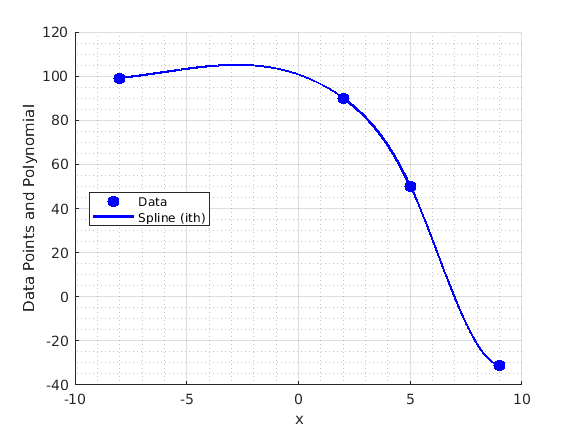

plotSplines(xData, yData, clmpSplines) % slope 1 at

% first endpointa nd slope -1 at last endpoint. 

% with the linsolve function
% % a1 b1 c1 d1 a2 b2 c2 d2 a3 b3 c3 d3
C = sym([0 0 0 1 0 0 0 0 0 0 0 0; % interp conditions
    0 0 0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 1; 
    1000 100 10 1 0 0 0 0 0 0 0 0; % continuity of f conditions
    0 0 0 0 27 9 3 1 0 0 0 0;
    0 0 0 0 0 0 0 0 64 16 4 1;
    300 20 1 0 0 0 -1 0 0 0 0 0; % cont. of f' conditions
    0 0 0 0 27 6 1 0 0 0 -1 0;
    60 2 0 0 0 -2 0 0 0 0 0 0; % cont. of f'' conditions
    0 0 0 0 18 2 0 0 0 -2 0 0;
    0 0 1 0 0 0 0 0 0 0 0 0;   % clamping: c1 = 0
    0 0 0 0 0 0 0 0 48 8 1 0]) % clamping: 48a3+8b3+c3 = -1

$$C = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 1000 & 100 & 10 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 9 & 3 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 64 & 16 & 4 & 1\\ 300 & 20 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 6 & 1 & 0 & 0 & 0 & -1 & 0\\ 60 & 2 & 0 & 0 & 0 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 18 & 2 & 0 & 0 & 0 & -2 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 48 & 8 & 1 & 0 \end{array}\right)$$

c = sym(transpose([99 90 50 90 50 -31 0 0 0 0 1 -1]))

$$c = \left(\begin{array}{c} 99\\ 90\\ 50\\ 90\\ 50\\ -31\\ 0\\ 0\\ 0\\ 0\\ 1\\ -1 \end{array}\right)$$

coefsClmp = linsolve(C, c);
ones = coefsClmp(1:4);
twos = coefsClmp(5:8);
threes = coefsClmp(9:12);
a1 = ones(1); b1 = ones(2); c1 = ones(3); d1 = ones(4);
a2 = twos(1); b2 = twos(2); c2 = twos(3); d2 = twos(4);
a3 = threes(1); b3 = threes(2); c3 = threes(3); d3 = threes(4);

[a1, b1, c1, d1] 

$$ans = \left(\begin{array}{cccc} -\frac{14557}{324000} & \frac{8401}{32400} & 1 & 99 \end{array}\right)$$


[a2 b2 c2 d2]

$$ans = \left(\begin{array}{cccc} -\frac{899}{2916} & -\frac{3527}{3240} & -\frac{23629}{3240} & 90 \end{array}\right)$$


[a3 b3 c3 d3]

$$ans = \left(\begin{array}{cccc} \frac{56219}{51840} & -\frac{12517}{3240} & -\frac{71761}{3240} & 50 \end{array}\right)$$

% or using the rref function
Cd = double(C);
cd = double(c);
coefsClmpDouble = rref([Cd, cd])

coefsClmpDouble =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0  -0.044943820224719
                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.259259259259259
                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.000000000000000
                   0                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   

coefsClmpDouble = coefsClmpDouble(:, end)

coefsClmpDouble =   -0.044943820224719
   0.259259259259259
   1.000000000000000
  99.000000000000000
  -0.308270676691729
  -1.088607594936709
  -7.292682926829269
  90.000000000000000
   1.084507042253521
  -3.863247863247863
 -22.148437500000000
  50.000000000000000


% See that they are (almost) equal
[double(vpa(coefsClmp)), coefsClmpDouble]

ans =   -0.044929012345679  -0.044943820224719
   0.259290123456790   0.259259259259259
   1.000000000000000   1.000000000000000
  99.000000000000000  99.000000000000000
  -0.308299039780521  -0.308270676691729
  -1.088580246913580  -1.088607594936709
  -7.292901234567902  -7.292682926829269
  90.000000000000000  90.000000000000000
   1.084471450617284   1.084507042253521
  -3.863271604938272  -3.863247863247863
 -22.148456790123458 -22.148437500000000
  50.000000000000000  50.000000000000000


fprintf('\n')

fprintf('\n')

Part c) not a knot cubic splines

knotSplines = notAKnotCubicSpline(xData, yData)

$$knotSplines = \left(\begin{array}{ccc} \frac{195428\,x}{23205}-\frac{5653\,{\left(x+8\right)}^{2}}{6188}-\frac{173\,{\left(x+8\right)}^{3}}{92820}+\frac{3860719}{23205} & -8 & 2\\ \frac{2571494}{23205}-\frac{857\,{\left(x-2\right)}^{2}}{884}-\frac{173\,{\left(x-2\right)}^{3}}{92820}-\frac{241522\,x}{23205} & 2 & 5\\ \frac{2438869}{18564}-\frac{15257\,{\left(x-5\right)}^{2}}{15470}-\frac{173\,{\left(x-5\right)}^{3}}{92820}-\frac{1510669\,x}{92820} & 5 & 9 \end{array}\right)$$

% decimal form
vpa(expand(knotSplines), 4)

$$ans = \left(\begin{array}{ccc} -0.001864\,x^{3}-0.9583\,x^{2}-6.553\,x+107.0 & -8.0 & 2.0\\ -0.001864\,x^{3}-0.9583\,x^{2}-6.553\,x+107.0 & 2.0 & 5.0\\ -0.001864\,x^{3}-0.9583\,x^{2}-6.553\,x+107.0 & 5.0 & 9.0 \end{array}\right)$$

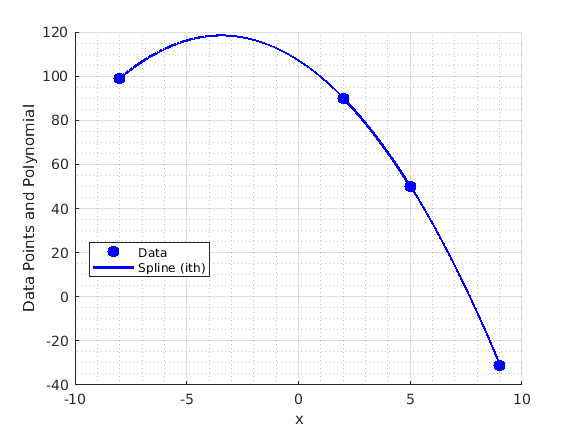

plotSplines(xData, yData, knotSplines) 

% with the linsolve function
% % a1 b1 c1 d1 a2 b2 c2 d2 a3 b3 c3 d3
K = sym([0 0 0 1 0 0 0 0 0 0 0 0; % interp conditions
    0 0 0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 0 0 0 0 0 0 1; 
    1000 100 10 1 0 0 0 0 0 0 0 0; % continuity of f conditions
    0 0 0 0 27 9 3 1 0 0 0 0;
    0 0 0 0 0 0 0 0 64 16 4 1;
    300 20 1 0 0 0 -1 0 0 0 0 0; % cont. of f' conditions
    0 0 0 0 27 6 1 0 0 0 -1 0;
    60 2 0 0 0 -2 0 0 0 0 0 0; % cont. of f'' conditions
    0 0 0 0 18 2 0 0 0 -2 0 0;
    1 0 0 0 -1 0 0 0 0 0 0 0;   % condition 5) a1 = a2
    0 0 0 0 1 0 0 0 -1 0 0 0]) % condition 6) a2 = a3

$$K = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 1000 & 100 & 10 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 9 & 3 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 64 & 16 & 4 & 1\\ 300 & 20 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 27 & 6 & 1 & 0 & 0 & 0 & -1 & 0\\ 60 & 2 & 0 & 0 & 0 & -2 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 18 & 2 & 0 & 0 & 0 & -2 & 0 & 0\\ 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & -1 & 0 & 0 & 0 \end{array}\right)$$

k = sym(transpose([99 90 50 90 50 -31 0 0 0 0 0 0]))

$$k = \left(\begin{array}{c} 99\\ 90\\ 50\\ 90\\ 50\\ -31\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

coefsKnot = linsolve(K, k);
ones = coefsKnot(1:4);
twos = coefsKnot(5:8);
threes = coefsKnot(9:12);
a1 = ones(1); b1 = ones(2); c1 = ones(3); d1 = ones(4);
a2 = twos(1); b2 = twos(2); c2 = twos(3); d2 = twos(4);
a3 = threes(1); b3 = threes(2); c3 = threes(3); d3 = threes(4);

[a1, b1, c1, d1] 

$$ans = \left(\begin{array}{cccc} -\frac{173}{92820} & -\frac{5653}{6188} & \frac{195428}{23205} & 99 \end{array}\right)$$


[a2 b2 c2 d2]

$$ans = \left(\begin{array}{cccc} -\frac{173}{92820} & -\frac{857}{884} & -\frac{241522}{23205} & 90 \end{array}\right)$$


[a3 b3 c3 d3]

$$ans = \left(\begin{array}{cccc} -\frac{173}{92820} & -\frac{15257}{15470} & -\frac{1510669}{92820} & 50 \end{array}\right)$$

% or using the rref function
Kd = double(K);
kd = double(k);
coefsKnotDouble = rref([Kd, kd])

coefsKnotDouble =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0  -0.001862197392924
                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0  -0.913580246913580
                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0   8.421875000000000
                   0                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   

coefsKnotDouble = coefsKnotDouble(:, end)

coefsKnotDouble =   -0.001862197392924
  -0.913580246913580
   8.421875000000000
  99.000000000000000
  -0.001862197392924
  -0.969696969696970
 -10.408163265306122
  90.000000000000000
  -0.001862197392924
  -0.986301369863014
 -16.274999999999999
  50.000000000000000


% See that they are (almost) equal
[double(vpa(coefsKnot)), coefsKnotDouble]

ans =   -0.001863822452058  -0.001862197392924
  -0.913542340012928  -0.913580246913580
   8.421805645335057   8.421875000000000
  99.000000000000000  99.000000000000000
  -0.001863822452058  -0.001862197392924
  -0.969457013574661  -0.969696969696970
 -10.408187890540832 -10.408163265306122
  90.000000000000000  90.000000000000000
  -0.001863822452058  -0.001862197392924
  -0.986231415643180  -0.986301369863014
 -16.275253178194355 -16.274999999999999
  50.000000000000000  50.000000000000000


Part d) fitting the  spline from matlab

yy_auto = spline(xData, yData, -8:0.01:9); % this is the
% not a knot spline. 

Plotting all three splines together

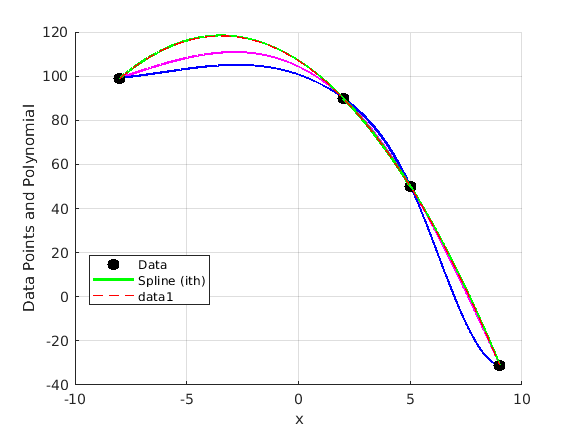

plotSplines(xData, yData, natSplines, 'm-')
plotSplines(xData, yData, clmpSplines, 'b-')
plotSplines(xData, yData, knotSplines, 'g-')
plot(-8:0.01:9, yy_auto, 'r--', 'LineWidth', 1)